Firstly, let's set the parameters for our project, based on the .pdf file in Canvas.

% Simulation time
t0 = 0;              % start time [days]
tf = 19;             % end time [days]
dt = 0.1;            % time resolution [days]
tspan = t0:dt:tf;    % time vector

% Initial Conditions (define separately for clarity)
T0 = 49.0497;   % Initial tumor volume [mm^3]
C0 = 0.171;     % Initial chemo drug concentration [mg/ml]

%% Tumor and Drug Parameters
C_M   = 1e4;           % Carrying capacity of tumor cells [mm^3]
d_c   = 0.1030;        % Natural death rate of tumor cells [/day]
b     = 0.1685;        % Death rate due to chemotherapy [/day]
lambda_ce = 0.4579;    % Tumor cell proliferation rate [/day]
d_d   = 0.1825;        % Clearance rate of chemotherapy drug [/day]
b_k   = 1.0839e-6;     % Drug clearance due to binding [mg/ml.day.mm^3]

%% Endothelial (Vascular) Parameters
E_thres = 4.5;         % Hypoxia threshold [mm^3]
lambda_e = 0.03;       % Endothelial proliferation rate [/day]
E_M   = 10;            % Carrying capacity of endothelial cells [mm^3]
d_e   = 0.05;          % Endothelial cell death rate [/day]

%% VEGF and Anti-VEGF Parameters
d_v   = 0.1;           % Natural decay rate of VEGF [/day]
d_b   = 0.005;         % Clearance rate of anti-VEGF drug [/day]
lambda_v0 = 1e-3;      % Baseline VEGF secretion rate [mg/ml.day.mm^3]
k     = 5;             % VEGF-induced endothelial proliferation [/day]
mu_B  = 10;            % VEGF removal when binding anti-VEGF [ml/day.mg]
mu_Bk = 0.15;          % Anti-VEGF clearance via binding [ml/day.mg]

%% Therapy Dosing Ranges (for future design or sensitivity analysis)
dose_chemo_range   = [0.002, 0.05];   % Chemotherapy dose [mg/ml]
dose_antiVEGF_range = [0.003, 0.07];  % Anti-VEGF dose [mg/ml]

% Add placeholders for future variables like VEGF, endothelial cells, etc.
E0 = 0.5 + (3-0.5)*rand;      % Initial endothelial density [mm^3] (within the 0.5–3 range)
V0 = 0.5 + (1.5-0.5)*rand;       % Initial VEGF [mg/ml] (within 0.5-1.5 range)
A0 = 0.213;      % Initial anti-VEGF drug concentration [mg/ml]

%% Matrix of coefficients with patients. Each row is a parameter, each column is a patient (by number in the .docx file)
% Order of rows:
% 1. Proliferation rate of the tumor cells
% 2. Carrying capacity tumor cells
% 3. Baseline VEGF secretion by tumor cells
% 4. Clearance of drugs by the kidneys


patients_coeffs = [
    1.20, 0.85, 1.50, 0.70, 1.05;  % Proliferation rate
    0.90, 0.80, 1.35, 1.05, 1.10;  % Carrying capacity
    1.50, 1.20, 0.90, 1.10, 0.80;  % VEGF secretion
    0.70, 1.10, 1.50, 0.85, 1.20   % Drug clearance
];

The Growth **model declaration **and** initial **results, with only **initial drugs dosing**.

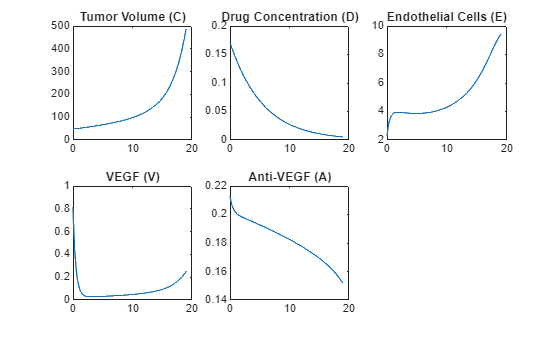

x0_extended = [T0; C0; E0; V0; A0];

params_extended = struct( ...
    'd_c', d_c, ...
    'b', b, ...
    'lambda_ce', lambda_ce, ...
    'd_d', d_d, ...
    'b_k', b_k, ...
    'c_M', C_M, ...
    'lambda_e', lambda_e, ...
    'd_e', d_e, ...
    'E_M', E_M, ...
    'd_v', d_v, ...
    'lambda_v0', lambda_v0, ...
    'd_b', d_b, ...
    'k', k, ...
    'mu_B', mu_B, ...
    'mu_Bk', mu_Bk ...
);

% Run simulation
[T1, Y1] = ode15s(@(t,y) Model_extended(t,y,params_extended), tspan, x0_extended);

% Plotting the variables of the extendedn model

figure;
subplot(2,3,1); plot(T1, Y1(:,1)); title('Tumor Volume (C)');
subplot(2,3,2); plot(T1, Y1(:,2)); title('Drug Concentration (D)');
subplot(2,3,3); plot(T1, Y1(:,3)); title('Endothelial Cells (E)');
subplot(2,3,4); plot(T1, Y1(:,4)); title('VEGF (V)');
subplot(2,3,5); plot(T1, Y1(:,5)); title('Anti-VEGF (A)');

The comparison between **no VEGF** and **yes VEGF/anti-VEGF drug**.

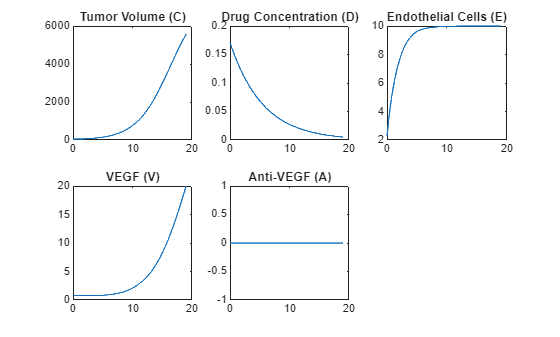

% Initial conditions (A0 = 0)
x0_no_anti_vegf = [T0; C0; E0; V0; 0];

% Run simulation using original Model_logistic (no VEGF, no E, no A)
[T2, Y2] = ode15s(@(t, y) Model_extended(t, y, params_extended), tspan, x0_no_anti_vegf);

% Plotting the variables of the extendedn model without anti-VEGF

figure;
subplot(2,3,1); plot(T2, Y2(:,1)); title('Tumor Volume (C)');
subplot(2,3,2); plot(T2, Y2(:,2)); title('Drug Concentration (D)');
subplot(2,3,3); plot(T2, Y2(:,3)); title('Endothelial Cells (E)');
subplot(2,3,4); plot(T2, Y2(:,4)); title('VEGF (V)');
subplot(2,3,5); plot(T2, Y2(:,5)); title('Anti-VEGF (A)');

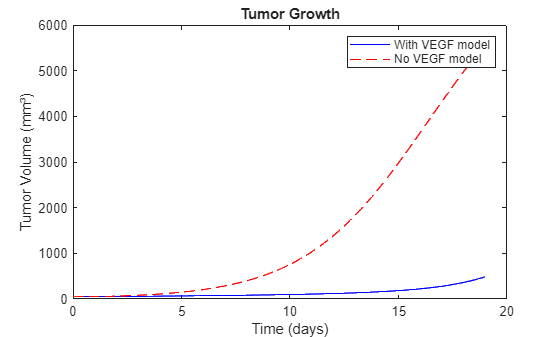


% Plotting Tumor volume (C) for difference between models

figure;
plot(T1, Y1(:,1), 'b-', T2, Y2(:,1), 'r--');
xlabel('Time (days)');
ylabel('Tumor Volume (mm³)');
title('Tumor Growth');
legend('With VEGF model', 'No VEGF model');


disp('Model_with_vegf:');

Model_with_vegf:


disp(Y1(1:5, :));

   49.0497    0.1710    2.2371    0.8171    0.2130
   49.0583    0.1679    2.6317    0.6598    0.2106
   49.1373    0.1649    2.9351    0.5337    0.2086
   49.2736    0.1619    3.1675    0.4334    0.2070
   49.4555    0.1590    3.3460    0.3537    0.2057



disp('Model_without_vegf:');

Model_without_vegf:


disp(Y2(1:5, :));

   49.0497    0.1710    2.2371    0.8171         0
   49.0678    0.1679    2.6747    0.8139         0
   49.1682    0.1649    3.0866    0.8107         0
   49.3531    0.1619    3.4721    0.8075         0
   49.6159    0.1590    3.8353    0.8044         0



The models playing with **continuous drugs dosing **(Work in progress).

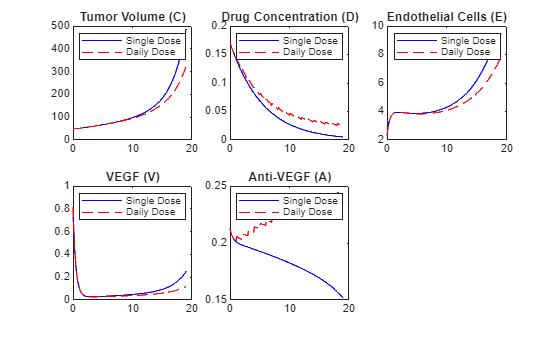

x0_everyday_injection = [T0; C0; E0; V0; A0];

%Computing the ODE for the 1st day

[T3, Y3] = ode15s(@(t, y) Model_extended(t, y, params_extended), [0:0.1:1], x0_everyday_injection); %[0:0.1:1] means simulating day 1, with numbers every 0.1 day

for i = 1:1:tf-1
    C_end = Y3(end,1);
    D_end = Y3(end,2) + 0.004; % inject chemotherapy daily
    E_end = Y3(end,3);
    V_end = Y3(end,4);
    A_end = Y3(end,5) + 0.005;  % inject anti-VEGF daily
    x0 = [C_end; D_end; E_end; V_end; A_end];
    t0 = T3(end);
    tf_step = t0 + 1;
    tstep = t0:dt:tf_step;
    [Tstep, Ystep] = ode15s(@(t, y) Model_extended(t, y, params_extended), tstep, x0);
    T3 = [T3; Tstep(2:end)];
    Y3 = [Y3; Ystep(2:end, :)];
end

figure;

subplot(2,3,1);
plot(T1, Y1(:,1), 'b-', T3, Y3(:,1), 'r--');
title('Tumor Volume (C)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,2);
plot(T1, Y1(:,2), 'b-', T3, Y3(:,2), 'r--');
title('Drug Concentration (D)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,3);
plot(T1, Y1(:,3), 'b-', T3, Y3(:,3), 'r--');
title('Endothelial Cells (E)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,4);
plot(T1, Y1(:,4), 'b-', T3, Y3(:,4), 'r--');
title('VEGF (V)');
legend('Single Dose', 'Daily Dose');

subplot(2,3,5);
plot(T1, Y1(:,5), 'b-', T3, Y3(:,5), 'r--');
title('Anti-VEGF (A)');
legend('Single Dose', 'Daily Dose');

The **function** needed to configure the model and calculate the tumour.

function dYdt = Model_extended(t, Y, params)

%Unpacking variables

C = Y(1);  % Tumor
D = Y(2);  % Drug
E = Y(3);  % Endothelial cells
V = Y(4);  % VEGF
A = Y(5);  % Anti-VEGF

%Unpacking the struct
d_c = params.d_c;
b = params.b;
lambda_ce = params.lambda_ce;
d_d = params.d_d;
b_k = params.b_k;
c_M = params.c_M;

lambda_e = params.lambda_e;
d_e = params.d_e;
E_M = params.E_M;

d_v = params.d_v;
lambda_v0 = params.lambda_v0;
d_b = params.d_b;
k = params.k;
mu_B = params.mu_B;
mu_Bk = params.mu_Bk;


%%Equations (not sure about them). No hypoxia is (yet) used.

dCdt = lambda_ce * C * (1 - C / c_M) * (E / E_M) - d_c * C - b * C * D * (E / E_M); % Using logistic model for the tumour growth, adding dependency on E
dDdt = -d_d * D - b_k * C * D * (E / E_M); % (E / E_M) adds dependency on the number of the endothelial cells and vascularisation.
%dEdt = lambda_e * k * V * (1 - E / E_M) - d_e * E; % Again, logistic for the endothelial cells growth, without dependency on C
dEdt = lambda_e * k * C * V * (1 - E / E_M) - d_e * E; % Again, logistic for the endothelial cells growth, including dependency on C
dVdt = lambda_v0 * C - d_v * V - mu_B * A * V;
dAdt = -d_b * A - mu_Bk * A * V;


% Return
dYdt = [dCdt; dDdt; dEdt; dVdt; dAdt];

end




In this practical, we use a type of MATLAB file called a **Live Script** (`.mlx`). A Live Script works like a blend of a Word document and a code notebook: it contains both text (which you can read like a handout) and short blocks of code that you can** execute with a single click**.

You won’t need to write any code from scratch — just **read the explanations**, **click "Run"**, and **observe the plots** that appear. Each plot shows how tumor growth or drug levels change over time, based on the mathematical model.

 **To run everything at once**, click the **“Run”** button at the top-right corner of MATLAB’s Live Editor.

 **To run just one section at a time**, click **“Run Section”** at the top center.

In this practical, we’re using code to simulate how cancer grows and responds to treatment using simple mathematical models. These models are described by systems of **ordinary differential equations (ODEs)**, which are solved and visualized in the code sections. The equations themselves are implemented as **functions**, which are listed at the end of this script.

**INTRODUCTION TO THE CANCER MODEL **

The model structure is schematically visualized below in figure 1.

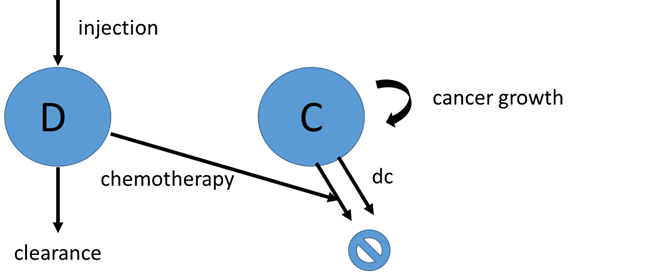Figure 1: Schematic structure of cancer growth model. 

The corresponding ODEs are as follows:

                                                                 (Eq 1)

                                                                           (Eq 2)

In which C represents the cancer cell density and D the chemotherapeutic concentration (e.g. docetaxel). 

What are the variables in the cancer growth model of Figure 1?

How many ODEs are required to describe the dynamics of this system?

What do the different terms in the equations represent? 

What are the parameters of the model?

The lines below plot the simulated cancer cell density and drug concentration as a function of time. Answer the following questions by** looking at the code** (either below or where the function is defined, at the end of the script)

Note. In MATLAB, functions are passed to the solver using the `@`** symbol**, like this: `@Model_exponential`. This tells MATLAB which model version (function) to use.

Which parameter values are assigned to these parameters? 

How is the injection of the drug modelled? Where can you find this in the code?

Which parameter(s) can be changed in order to reduce tumor growth? Is it possible to fully stop tumor growth? 

 **Run this section** and look at the plots. What can you observe?

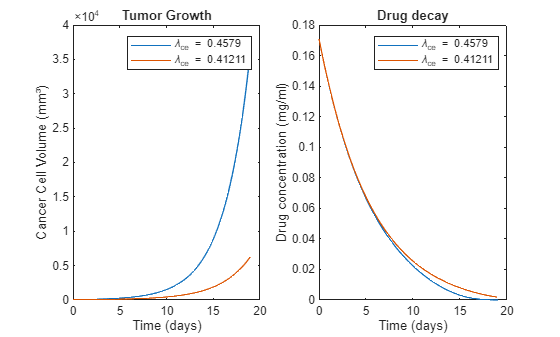

% Set simulation time
t0 = 0; tf = 19;  % in days

% Initial conditions
x0 = [49.0497; 0.171];
tspan = [0:0.1: 19];

% Parameters
params = struct( ...
    'd_c', 0.1030, ...
    'b', 0.1685, ...
    'lambda_ce', 0.4579, ...
    'd_d', 0.1825, ...
    'b_k', 5e-5);

% Solve Model
[T, X1] = ode15s(@(t,y) Model_exponential(t,y,params), tspan, x0);

params2 = struct( ...
    'd_c', 0.1030, ...
    'b', 1.1685, ...
    'lambda_ce', 0.4579*0.9, ... #this parameter was reduced - what parameter is this? what is the effect? - you can change the value and run the section again
    'd_d', 0.1825, ...
    'b_k', 5e-5);

% Solve Model for different parameter values 
[T, X2] = ode15s(@(t,y) Model_exponential(t,y,params2), tspan, x0);

% Plot tumor volume and drug concentration
figure;
subplot(1,2,1);
subplot(1,2,1)
xlim([0.12 1.12])
ylim([0.377 1.377])
plot(T, X1(:,1),T,X2(:,1));
xlabel('Time (days)');
ylabel('Cancer Cell Volume (mm³)');
title('Tumor Growth');
legend(... %this is just to plot the legend, copying the value from the params structure - update this part if you modify a different parameter
    ['\lambda_{ce} = ' num2str(params.lambda_ce)], ... #converting number to string to write the legend caption 
    ['\lambda_{ce} = ' num2str(params2.lambda_ce)] ...
);

subplot(1,2,2);
plot(T, X1(:,2),T,X2(:,2)); %overlapping
title('Drug decay');
ylabel('Drug concentration (mg/ml)');
xlabel('Time (days)');
legend(... %this is just to plot the legend, copying the value from the params structure - update this part if you modify a different parameter
    ['\lambda_{ce} = ' num2str(params.lambda_ce)], ...
    ['\lambda_{ce} = ' num2str(params2.lambda_ce)] ...
);

Play with the parameter values of Model_exponential.m and re-run the plots.

**INTRODUCING LOGISTIC GROWTH **

Look at the function **Model_logistic** - that describes the cancer model of figure 1 but instead of exponential growth implements logistic growth. 

The corresponding ODEs are as follows:

                                                                 (Eq 3)

                                                                           (Eq 2)

Which equation (term) is different with respect to Model_exponential? 

What does this represent?

**Run the code below** to plot the simulated cancer cell density and drug concentration as a function of time. Compare with basic growth model. What do you observe? Is this what you expect? 

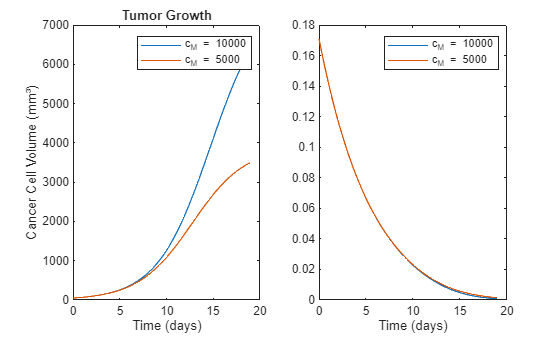

% Set simulation time
tspan = 0:0.1: 19;

% Initial conditions: [Cancer Volume C (mm³); Drug Concentration D (mg/ml)]
x0 = [49.0497; 0.171];

% Parameters
params = struct( ...
    'd_c', 0.1030, ...
    'b', 0.1685, ...
    'lambda_ce', 0.4579, ...
    'd_d', 0.1825, ...
    'b_k', 5e-5, ...
    'c_M', 1e4 ... # this parameter was added - not present in the previous function
);

% Solve ODE using Model logistic
[T, X1] = ode15s(@(t,y) Model_logistic(t,y,params), tspan, x0);

% Parameters - modified values
params2 = struct( ...
    'd_c', 0.1030, ...
    'b', 0.1685, ...
    'lambda_ce', 0.4579, ...
    'd_d', 0.1825, ...
    'b_k', 5e-5, ...
    'c_M', 5*1e3 ... #this parameter was decreased
);

% SOlve for different parameter values
[T, X2] = ode15s(@(t,y) Model_logistic(t,y,params2), tspan, x0);

% Plot tumor volume and drug concentration
figure;
subplot(1,2,1);
plot(T, X1(:,1), T,X2(:,1) );
xlabel('Time (days)');
ylabel('Cancer Cell Volume (mm³)');
title('Tumor Growth');
legend(... #this is just to plot the legend, copying the value from the params structure - update this part if you modify a different parameter
    ['c_M = ' num2str(params.c_M)], ... %function to convert number into text to write the caption 
    ['c_M = ' num2str(params2.c_M)] ...
);


subplot(1,2,2);
plot(T,X1(:,2),T,X2(:,2));
xlabel('Time (days)');
legend(... #this is just to plot the legend, copying the value from the params structure - update this part if you modify a different parameter
    ['c_M = ' num2str(params.c_M)], ... 
    ['c_M = ' num2str(params2.c_M)] ...
);

Is it possible to fully stop tumor growth? Play with the parameter values of Model_logistic.m and re-run the plots. 

**MODEL PARAMETRIZATION**

So far we have worked with estimated parameter values, but our experimental collaborators have done some measurements of the chemotherapeutic drug concentration as a function of time. 

We are confident in the estimates of the clearance rate (determined from urine measurements), so this dataset allows us to **more accurately determine bk**. 

In the code below, where is the experimental data assigned and where is it used (mention the lines)? 

Which function was used to find the optimal value for the parameter bk?

Note. A new @function was defined - you can find it at the end of the script

Which definition of error is used? 

%% MODEL PARAMETERIZATION 

% Set the time of the simulation
t0 = 0; tf = 19;  %(day)
% Set the initial condition
x0 = [49.0497;0.171];

%parameters before optimization
b_k_old = 5*10^-5; % b_k value - to be optimized using data 

params = struct( ...
    'd_c', 0.1030, ...
    'b', 0.1685, ...
    'lambda_ce', 0.4579, ...
    'd_d', 0.1825, ...
    'b_k', b_k_old, ...
    'c_M', 1e4 ... 
);

lb = 10^(-10); %lower bound of the range in which we will try to find a better b_k parameter value
ub = 10^(-4); %upper bound of the range in which we will try to find a better b_k parameter value
options = optimset('Display', 'Iter');

%optimize model logistic growth
%experimental data
datT= [0.149 0.298 0.448 0.905 1.36 1.82 2.278 3.268 4.258 5.247 6.237 7.22 8.38 9.55 10.71 11.87 13.03 14.19 15.460 16.72 17.99 19];
%times at which the drug concentration was measured
datD =[0.166 0.161 0.157 0.145 0.133 0.122 0.112 0.094 0.078 0.065 0.054 0.045 0.0365 0.029 0.023 0.018 0.0148 0.0117 0.0089 0.0066 0.00489 0.0037];
%chemotherapeutic drug concentration data

%algorithm to minimize the error between the predicted and experimental
[res.x,res.resnorm,res.residual,res.exitflag,res.output,res.lambda,res.jacobian] = lsqnonlin(@(b_k)costFunct(b_k,datT,datD),b_k_old,lb,ub,options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          2           2.23738                             1.54
     1          4          0.382417      0.00409035            0.558      
     2          6         0.0440734      0.00185895            0.139      
     3          8        0.00482093     0.000804709           0.0226      
     4         10        0.00330672     0.000196817           0.0011      
     5         12        0.00330277     1.08403e-05         7.62e-06      
     6         14        0.00330277     2.37524e-09         7.62e-06      

Local minimum possible.
lsqnonlin stopped because the size of the current step is less than
the value of the 

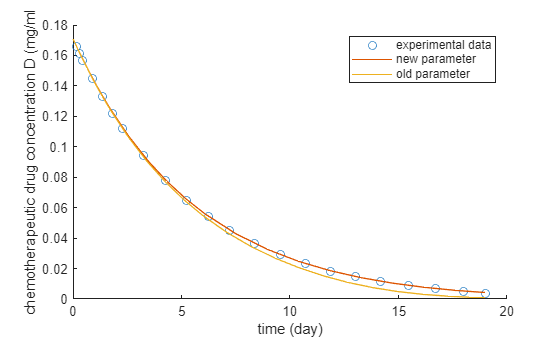

%b_k values optimized  
b_kopt =res.x;
% Parameters - with optimized b_k
params_opt = struct( ...
    'd_c', 0.1030, ...
    'b', 0.1685, ...
    'lambda_ce', 0.4579, ...
    'd_d', 0.1825, ...
    'b_k', b_kopt, ... #optimized value
    'c_M', 5*1e3 ... 
);


[Tnew,Ynew] = ode15s(@(t,y) Model_logistic(t,y,params_opt),[t0 tf],x0);
[Told,Yold] = ode15s(@(t,y) Model_logistic(t,y,params),[t0 tf],x0);
figure;
scatter(datT,datD);
hold on
plot(Tnew,Ynew(:,2))
plot(Told,Yold(:,2))
xlabel('time (day)');
ylabel('chemotherapeutic drug concentration D (mg/ml');
legend('experimental data', 'new parameter', 'old parameter')

What was the old value for bk? What is the optimized value? Is it a better fit? 

**MODEL USE: THERAPY OPTIMIZATION**

We have now parameterized the model. Considering all side effects arising from the chemotherapeutic drugs we want to optimize the therapeutic regimen by optimizing the dose and timing of administration. In other words is it better to have 1 injection (large dose, at time zero, implemented as the initial condition) or multiple injections (but smaller dosing)? 

Which cases are implemented? 

 What do you observe? 

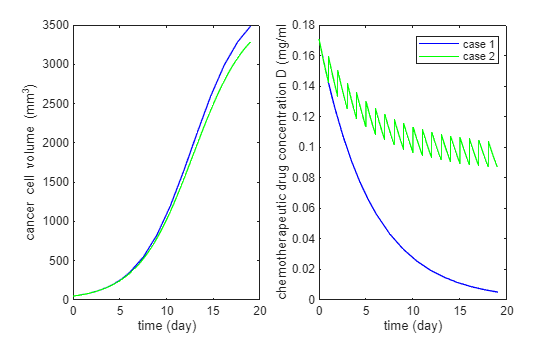

%% MODEL USE: THERAPY OPTIMIZATION 
% simulate different cases of cancer growth and drug therapies 

%we are now using the optimized value of b_k
b_kopt = 1.0839*10^(-6);
% Parameters - with optimized b_k
params_opt = struct( ...
    'd_c', 0.1030, ...
    'b', 0.1685, ...
    'lambda_ce', 0.4579, ...
    'd_d', 0.1825, ...
    'b_k', b_kopt, ... #optimized value
    'c_M', 5*1e3 ... 
);


% CASE 1 - reduced model logistic with 1 injection 
% Set the time of the simulation
t0 = 0; tf = 19;  %(day)

% Set the initial condition
x0 = [49.0497;0.171];

% Solve the ODE system
[T1,X1] = ode15s(@(t,y) Model_logistic(t,y,params_opt),[t0 tf],x0);

% CASE 2 - reduced model logistic with multiple injections 
% Set the time of the simulation
t0 = 0; tf = 1;  %(day)

% Set the initial condition
x0 = [49.0497;0.171];

% Solve the ODE system
%opts = odeset('RelTol',1e-10,'AbsTol',1e-12);
[T,X] = ode15s(@(t,y) Model_logistic(t,y,params_opt),[0:0.1:1],x0);
% for loop is used to do an injection every day
for i=1:1:18
    x0=[X(end,1); X(end,2)+0.0171];
    t0=T(end);
    tf=T(end)+1;
    [Tstep,Xstep] = ode15s(@(t,y) Model_logistic(t,y,params_opt),[t0 tf],x0);
    T=[T;Tstep];
    X=[X;Xstep];
    T2=T;
    X2=X;
end 

%figure 2 plots
figure;
subplot(1,2,1);
plot(T1,X1(:,1),'b-',T2,X2(:,1),'g-');
xlabel('time');
xlabel('time (day)');
ylabel('cancer cell volume (mm^3)');

subplot(1,2,2);
plot(T1,X1(:,2),'b-',T2,X2(:,2),'g-');
xlabel('time');

legend('case 1', 'case 2')
xlabel('time (day)');
ylabel('chemotherapeutic drug concentration D (mg/ml')

## [Extra] Model analysis : Sensitivity analysis 

When going to clinical applications, you need to fully analyze the system, to demonstrate we can trust the predictions. One such analysis quantifies how the parameter settings, in which we might not have 100% confidence, influence the model outcome. In the code below, we investigate the effect of changing some parameters by 50% on the tumor size. 

Which parameters are investigated? 

How is the parameter sensitivity calculated? 

**Run the section**. What do you observe? 

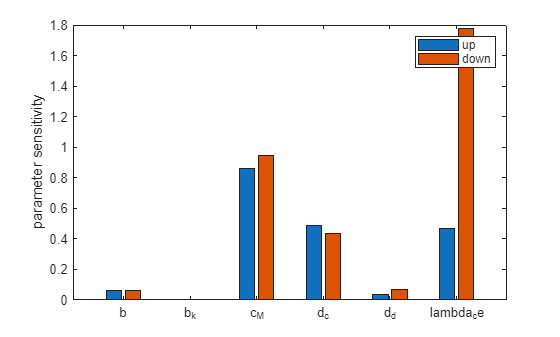

a=0.5; %change in parameter (50%)

% Parameters - with optimized b_k
p = struct( ...
    'd_c', 0.1030, ...
    'b', 0.1685, ...
    'lambda_ce', 0.4579, ...
    'd_d', 0.1825, ...
    'b_k', 1.0839*10^(-6), ... #optimized b_k
    'c_M', 5*1e3 ... 
);

% calculate baseline outcome 
% outcome = tumor size at time 19
% Set the time of the simulation
t0 = 0; tf = 1;  %(day)
% Set the initial condition
% C, D
x0 = [49.0497;0.0171];

% Solve the ODE system
%opts = odeset('RelTol',1e-10,'AbsTol',1e-12);
[T,X] = ode15s(@(t,y) Model_logistic(t,y,p),[t0 tf],x0);

for i=1:1:18
    x0=[X(end,1); X(end,2)+0.0171];
    t0=T(end);
    tf=T(end)+1;
    [Tstep,Xstep] = ode15s(@(t,y) Model_logistic(t,y,p),[t0 tf],x0);
    T=[T;Tstep];
    X=[X;Xstep];
end 

tumor_size=X(end,1);

sensitivities = zeros(size(p,2),2); %create a vector to store the calculate sensitivities
%first column is up, second column is down 
fields= ["c_M" "d_c" "b" "lambda_ce" "d_d" "b_k"];

for j=1:1:size(fields,2)

    
    %change the parameter up
    p_new=p;
    p_new.(fields(j))=p.(fields(j))+a*p.(fields(j));

    %calculate outcome
    
    % Set the time of the simulation
    t0 = 0; tf = 1;  %(day)
    % Set the initial condition
    % C, D
    x0 = [49.0497;0.0171];
    % Solve the ODE system
    %opts = odeset('RelTol',1e-10,'AbsTol',1e-12);
    [T,X] = ode15s(@(t,y) Model_logistic(t,y,p_new),[t0 tf],x0);
    for i=1:1:18
        x0=[X(end,1); X(end,2)+0.0171];
        t0=T(end);
        tf=T(end)+1;
        [Tstep,Xstep] = ode15s(@(t,y) Model_logistic(t,y,p_new),[t0 tf],x0);
        T=[T;Tstep];
        X=[X;Xstep];
    end 
    tumor_size_altered=X(end,1);
    %calculate parameter sensitivity 
    ps = (abs(tumor_size_altered-tumor_size)/tumor_size)/a;
    sensitivities(j,1)=ps;

    %change the parameter down 
    p_new=p;
    p_new.(fields(j))=p.(fields(j))-a*p.(fields(j));

    %calculate outcome
    
    % Set the time of the simulation
    t0 = 0; tf = 1;  %(day)
    % Set the initial condition
    % C, D
    x0 = [49.0497;0.0171];
    % Solve the ODE system
    %opts = odeset('RelTol',1e-10,'AbsTol',1e-12);
    [T,X] = ode15s(@(t,y) Model_logistic(t,y,p_new),[t0 tf],x0);
    for i=1:1:18
        x0=[X(end,1); X(end,2)+0.0171];
        t0=T(end);
        tf=T(end)+1;
        [Tstep,Xstep] = ode15s(@(t,y) Model_logistic(t,y,p_new),[t0 tf],x0);
        T=[T;Tstep];
        X=[X;Xstep];
    end 
    tumor_size_altered=X(end,1);
    %calculate parameter sensitivity 
    ps = (abs(tumor_size_altered-tumor_size)/tumor_size)/a;
     sensitivities(j,2)=ps;
end
figure;


%bar(x,sensitivities)
bar(categorical(fields),sensitivities)
legend('up','down')
ylabel('parameter sensitivity');

**The original functions of the model, without the extension**



%% Embedded Model Functions
% The following functions define the ODE models used above.

%% Basic Cancer Model with Exponential Growth

function dYdt = Model_exponential(t,Y, params)
% ODE cancer model, including cancer cells (C), chemotherapy drug (e.g. docetaxel) (D)
%
% input: 
% - t:  time
% - Y:  vector of state variables (C, D)
% - params: parameter values 
% - dYdt:   column vector of derivatives

     % Parameters
    d_c = params.d_c; % day-1
    b = params.b; % ml/mg.day
    lambda_ce = params.lambda_ce; %1/day
    d_d = params.d_d; %1/day
    b_k = params.b_k; % 1/day.mm^3

    % Variables
    C = Y(1);  %cancer cells 
    D = Y(2);  %chemotherapy drug concentration (e.g. docetaxel) 
    %2 variables -> 2 ODEs 
    % ODEs
    dCdt = lambda_ce * C - d_c * C - b * C * D;
    dDdt = -d_d * D - b_k * C * D;
    
    %create output column vector dYdt
    dYdt = [dCdt; dDdt];
end

%% Logistic Cancer Growth Model
function dYdt = Model_logistic(t, Y, params)
% ODE cancer model, including cancer cells (C), chemotherapy drug (e.g. docetaxel) (D)
%
% input: 
% - t:  time
% - Y:  vector of state variables (C, D)
% - dYdt:   column vector of derivatives
    % Parameters
    c_M = params.c_M; % mm^3
    d_c = params.d_c; % day-1
    b = params.b;  % ml/mg.day
    lambda_ce = params.lambda_ce; %1/day
    d_d = params.d_d; %1/day
    b_k = params.b_k; % 1/day.mm^3

    % Variables
    C = Y(1);
    D = Y(2);

    % ODEs
    dCdt = lambda_ce * C * (1-C/c_M) - d_c * C - b * C * D;
    dDdt = -d_d * D - b_k * C * D;
    
    dYdt = [dCdt; dDdt]; 
end



%% Logistic Cancer Growth Model with b_k as parameter 
function dYdt = Model_logistic_optimize(t,Y,p)
    % Parameters
    c_M = 1e4;           % mm^3 (carrying capacity)
    d_c = 0.1030;        % 1/day
    b = 0.1685;          % ml/mg.day
    lambda_ce = 0.4579;  % 1/day
    d_d = 0.1825;        % 1/day
    b_k = p;             % 1/day.mm^3

    % Variables
    C = Y(1); % cancer cells
    D = Y(2); % drug concentration

    % ODEs
    dCdt = lambda_ce*C*(1 - C/c_M) - d_c*C - b*C*D;
    dDdt = -d_d*D - b_k*C*D;

    dYdt = [dCdt; dDdt];
end


function error = costFunct(p,datT,datD)

% Set the time of the simulation
t0 = 0; tf = 19;  %(day)
% Set the initial condition
% C, D
x0 = [49.0497;0.171];

params = struct( ...
    'd_c', 0.1030, ...
    'b', 0.1685, ...
    'lambda_ce', 0.4579, ...
    'd_d', 0.1825, ...
    'b_k', p, ...% at each iteraton, p has a new value, and params is updated before solving the ODEs
    'c_M', 1e4 ... 
);

[T,Y] = ode15s(@(t,y) Model_logistic(t,y,params),[t0 tf],x0);

%interpolate simulated drug values at measured time points 
measured_times = datT'; %converts row into column
simulated_times = T;
simulated_drug_values = Y(:,2); 

% Interpolate simulated drug values at measured time points
interpolated_drug_values = interp1(simulated_times, simulated_drug_values, measured_times);

error = (interpolated_drug_values - datD')./datD'; 

end


